# Artificial models & Diagnosis

Clear workspace

clear all; clc; close all;

## Generate artificial data set

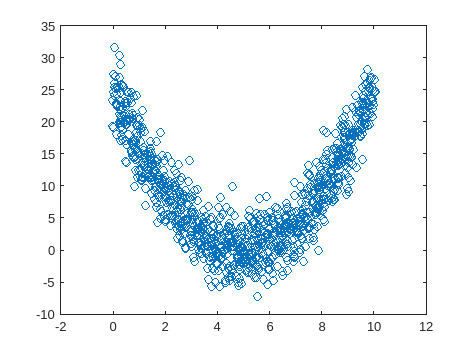

x = 0:0.01:10;
x = x+randn(1,1001)*0.1;
y = (5-x).^2 + randn(1,1001)*3;
x = x';
y = y';
figure(1)
plot(x,y,'o')

## Linear model

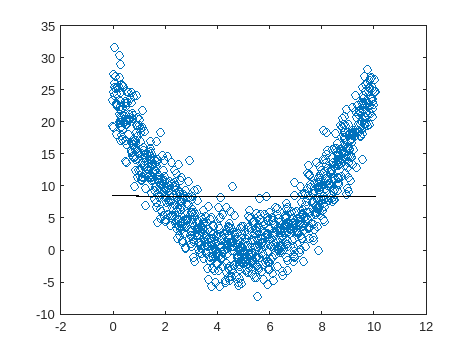

lm = fitlm(x,y);
ypred = predict(lm,x);
X = [ones(size(x,1),1) x];
[b, bint, r, rint, stats] = regress(y,X);
figure(2)
plot(x,y,'o')
hold on
plot(x,ypred,'k')
hold off

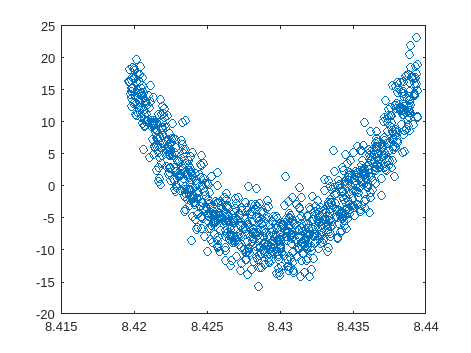


%residuals vs predicted var
figure(3)
plot(ypred,r,'o')

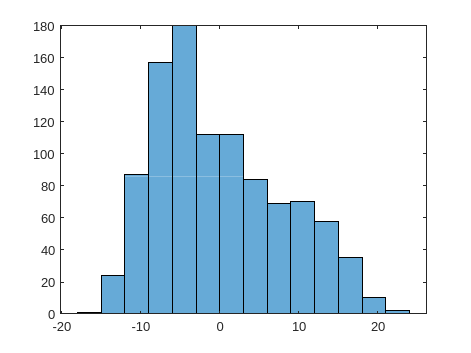


figure(4)
histogram(r)

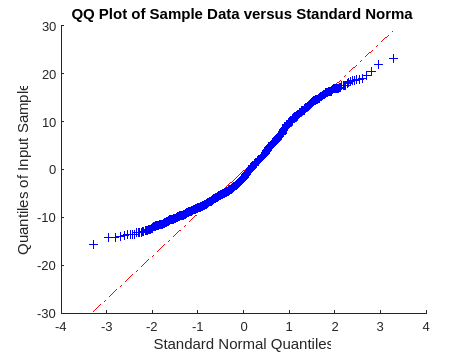


figure(5)
qqplot(r)

### KSTEST (Kolmogorov-Smirnov test)

[h, p, ksstat, cv] = kstest(r)

h = logical
   1


p = 2.0446e-195

ksstat = 0.4722

cv = 0.0428

## Quadratic model

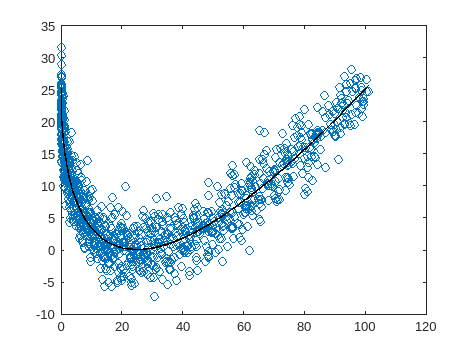

x = [x x.^2];
lm = fitlm(x,y);
ypred = predict(lm,x);
X = [ones(size(x,1),1) x];
[b, bint, r, rint, stats] = regress(y,X);
figure(10)
plot(x(:,2),y,'o')
hold on
plot(x(:,2),ypred,'k')
hold off

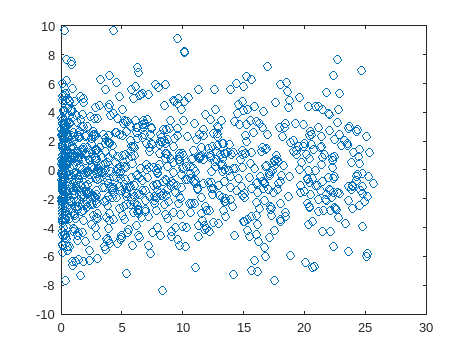


%residuals vs predicted var
figure(11)
plot(ypred,r,'o')

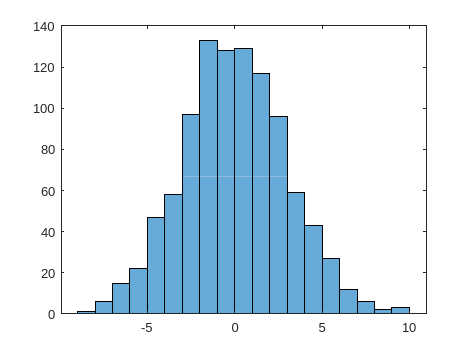


figure(12)
histogram(r)

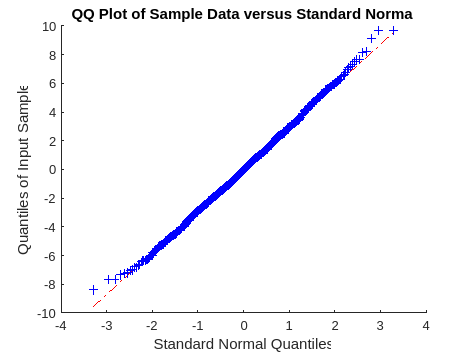


figure(13)
qqplot(r)

### KSTEST (Kolmogorov-Smirnov test)

[h, p, ksstat, cv] = kstest(r)

h = logical
   1


p = 5.5469e-53

ksstat = 0.2451

cv = 0.0428

## K-S test for residuals

% Normal distribution sample
sample = randn(101,1);
[h, p, ksstat, cv] = kstest(sample)

h = logical
   0


p = 0.6436

ksstat = 0.0721

cv = 0.1334


xx = [0:0.1:10]';
yy = xx + sample;
[b, bint, r, rint, stats] = regress(yy, [ones(size(xx,1),1) xx]);
[h, p, ksstat, cv] = kstest(r)

h = logical
   0


p = 0.6642

ksstat = 0.0709

cv = 0.1334

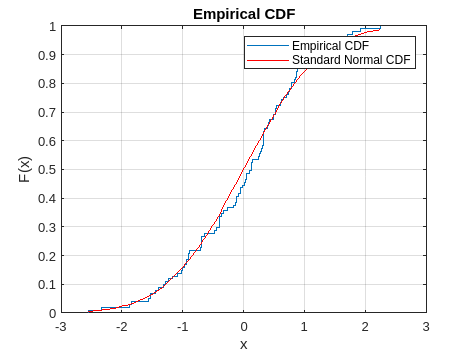


figure(20)
clf
cdfplot(r)
hold on
r_values = linspace(min(r), max(r));
plot(r_values, normcdf(r_values,0,1), 'r-')
legend('Empirical CDF', 'Standard Normal CDF')

% Uniform distribution sample
sample = rand(101,1);
[h, p, ksstat, cv] = kstest(sample)

h = logical
   1


p = 2.8591e-23

ksstat = 0.5044

cv = 0.1334


xx = [0:0.1:10]';
yy = xx + sample;
[b, bint, r, rint, stats] = regress(yy, [ones(size(xx,1),1) xx]);
[h, p, ksstat, cv] = kstest(r)

h = logical
   1


p = 3.1395e-09

ksstat = 0.3131

cv = 0.1334

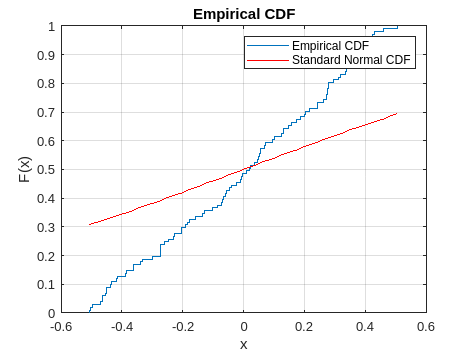


figure(21)
clf
cdfplot(r)
hold on
r_values = linspace(min(r), max(r));
plot(r_values, normcdf(r_values,0,1), 'r-')
legend('Empirical CDF', 'Standard Normal CDF')
hold off

## QQplot

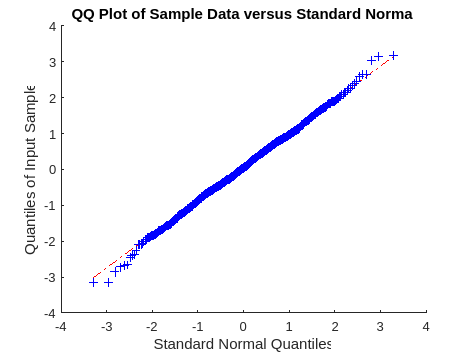

% Normal distrib
sample = randn(1000,1);
figure(22)
qqplot(sample)

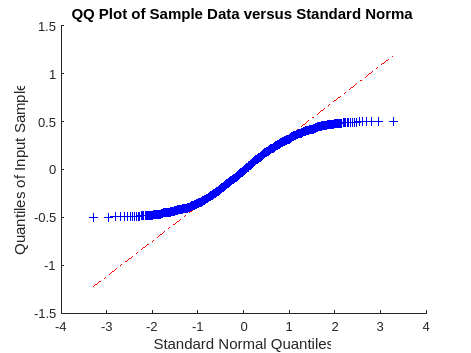

% Uniform distrib
sample = rand(1000,1)-0.5;
figure(23)
qqplot(sample)

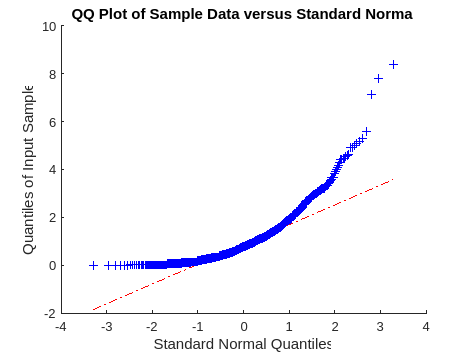

% Exponential distrib
sample=exprnd(1,1000,1);
figure(24)
qqplot(sample)

## Jarque-Bera test

% Normal distrib sample
sample = randn(1000,1);
[h, p, jbstat, critval] = jbtest(sample)

h = 0

p = 0.1029

jbstat = 4.3999

critval = 5.9282

% Uniform distrib sample
sample = rand(1000,1)-0.5;
[h, p, jbstat, critval] = jbtest(sample)

h = 1

p = 1.0000e-03

jbstat = 59.7718

critval = 5.9282